# Bioreactor Optimization and Parameter Estimation for Reaction Kinetics

## Computational Tools Needed

MATLAB, Optimization Toolbox, Global Optimization Toolbox, Curve Fitting Toolbox

## Learning Objectives

- Optimizing bioreactor operation by identifying free variables, objective function and implementing the solution using MATLAB and Global Optimization Toolbox.

- Estimating reaction kinetics parameters from concentration and rate data using MATLAB, Curve Fitting Toolbox and Optimization Toolbox.

- Setting up optimization problems programmatically and interactively using Live Tasks.

## Bioreactor Optimization

Let's revisit "Bacteria Growth in a Batch Reactor" exercise. In this exercise, we manually changed the initial conditions like the initial concentration of cells and substrate and observed how the cell concentration, substrate concentration, product concentration and the cell growth rate with inhibition changed over time. Now, let's focus on how we can change the initial cell concentration and the initial substrate concentration for a given range values such that we achieve the maximum product concentration. This is an optimization problem and we will solve this problem using MATLAB and Optimization Toolbox. 

- Optimization problems require an objective function. 

- In order to have an optimization problem, we need to have free variables. If the degrees of freedom is 0, it means the problem may have a unique solution and it is not an optimization problem. In this case, we have free variables, the initial conditions of the concentrations that we can freely change to fulfill our objective function.

- We will impose constraints i.e. upper and lower bounds for the concentrations and we will seek a maximum in such a way that the constraints are satisfied.

 **Exercise 1: **Modify the code from "Bacteria Growth in a Batch Reactor" into an optimization problem. Use the cell and substrate concentration lower and upper bounds and time span given below. The objective is maximizing the product concentration, $C_p$. Use [surrogateopt ](https://www.mathworks.com/help/gads/surrogateopt.html)to optimize the objective function. Keep in mind that this function solves a minimization problem. Since we want to maximize our function, the objective function must be multiplied with -1. The maximum product concentration can occur at anytime in the timespan. Make sure to pick the maximum value in the timespan. Generate the same plots as "Bacteria Growth in a Batch Reactor" for the optimized values of the initial conditions and the optimized product concentration.

**Step 1: **This time, we will demonstrate how we can define the parameters outside the function where the differential equation was defined. We will pass these parameters into the differential equation and objective function. We also define the time span and the lower and upper bounds for the initial cell and substrate concentrations. Follow the example to write your code.

% write your code here


**Step 2: **Define the objective function and pass the parameters needed for the calculations. Our optimization variables are in x. We are solving a maximization problem, that's why we are multiplying the objective function with -1. Follow the example below. You can display the optimized results' values by removing ; from the last 2 lines of the example.

% write your code here


**Step 3: **While we are solving the optimization problem, we will solve our differential equations for a combination of variables, but we are only interested in the results for the optimized combination. Although we can store the solutions and return the results, this is not very memory friendly. Instead, we will return only the optimized variables and solve the differential equations with the optimized results again. Follow the example below to write your code.

% write your code here


**Step 4: **Visualize the ODE solutions like you did in Day 1. 

% write your code here




**Step 5: **Optimization objective function calls an ODE solver to solve our differential equations and returns the maximum value of the product concentration. Let's write this helper function as shown in the example:

**Step 6: **We need another helper function to define the set of ODEs we are solving. Note that this function is taking more inputs compared to the function we defined in Day 1. This is because we defined the parameters outside the function. Let's define our helper function as follows: 

% write your code here



  ** Try: **

- What happens if you change the initial cell and substrate conditions' lower and upper bounds? 

- Do you need an initial guess for surrogate function to solve the optimization problem?

- What happens if you change the optimization options?

## Parameter Estimation for Reaction Kinetics

In the previous exercises, we used parameters like $Y_{s|c}$, $Y_{p|c}$, $\mu_{\max }$ and $K_s$. Typically, in the reaction kinetics experiments, concentrations are measured and these parameters are estimated using concentration vs. time data and with the aid of some equations. In this section, we will learn how to do parameter estimation using reaction kinetics data. We will use MATLAB and Curve Fitting Toolbox. 

 **Exercise 2: **The following data is obtained in a batch reactor. Assume that there is no lag and maintenance at the start of the growth is negligible. Using the data and the listed equation, estimate $Y_{c|s}$

 $C_c =Y_{c|s} \left(C_{\textrm{s0}} -C_s \right)$           **(Equation 1)**

**Reaction Kinetics Data:**


$$\textrm{Substrate}+\textrm{Cells}\to \textrm{More}\;\textrm{cells}+\textrm{Product}$$


%Synthetically generate experimental data for Cc to obtain Ycs by curve
%fitting.
clear vars; 
n=10;
time= linspace(0,3,n)';
Ytrue=0.063;
Cs0 = 220;
Cs=linspace(Cs0,200,n)';
delta_Cs=Cs0-Cs;
noise=0.01*rand(n,1);
Cc=Ytrue * delta_Cs .* (1 + noise);



Calculate $Y_{c|s} \;$from the reaction data given above using Equation 1.

** Interactive exercise:**

- Now that we have $\Delta C_s$, let's navigate to MATLAB Apps tab -> Curve Fitter.  In Curve Fitter app, click on "Select Data", select "delta_Cs" as x-data and Cc as y-data, hit "Close". Select "Custom Equation" in Regression Models and enter your custom equation i.e. y=a*x to obtain $Y_{c|s}$  You will see fit results in the "Results" tab along with Goodness of Fit information. You can export the results or generate a code if you like to apply this model to a different dataset. "Generate Code" and explore autogenerated code. 

 **Exercise 3: **Using the reaction data from Exercise 2 and Equation 2 below, estimate $\mu_{\max }$ and $K_s$. To estimate these parameters, navigate to "Insert" tab in Live Editor, select "Live Task" in the toolstrip, and search for "Optimize". In the Optimize Live Task, select "Problem-based" approach, create optimization variables   $0\ldotp 0001<\mu_{\max } <5$ and $0\ldotp 0001<K_s <3$. In "Define Problem" section, select "Solve Equations" and type Equation 2 as follows:

rg-((mumax*Cc.*Cs)./(Ks+Cs))

$r_g -\frac{\mu_{\max } C_c C_s }{K_s +C_s }=0$           **(Equation 2)**

%Synthetically generate experimental data for rg
Kstrue=2.5;
mumaxtrue=0.5;
rg=mumaxtrue*(Cc.*Cs)./(Kstrue+Cs).* (1 +0.1*noise);


Your Optimize Live Task should look like this:

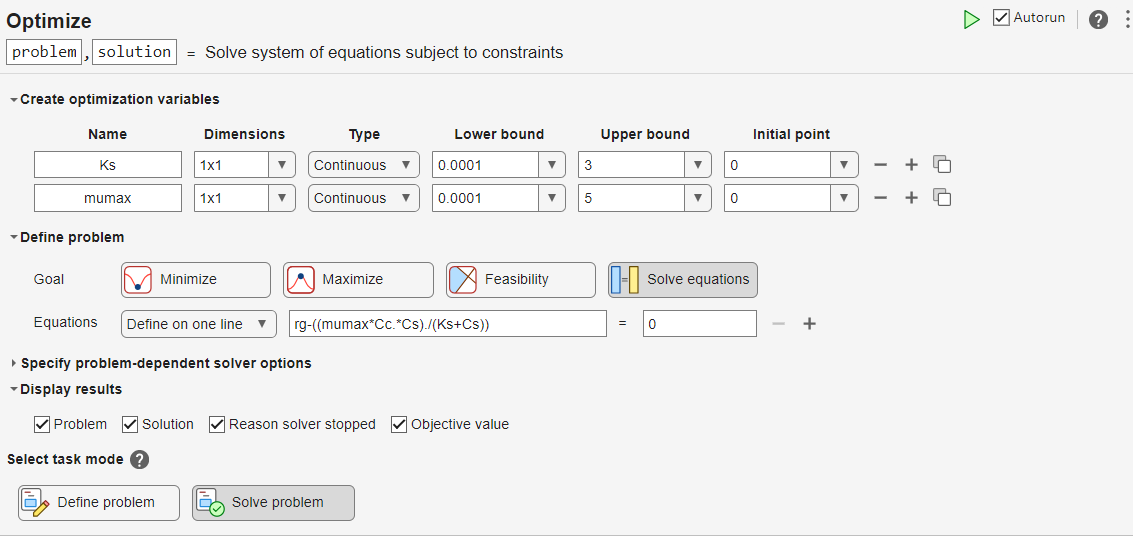

### **Things to Consider:**

- We can also estimate parameters to differential equations by formulating parameter estimation problem as an optimization problem. You can explore this approach by studying [Fit ODE Parameters Using Optimization Variables](https://www.mathworks.com/help/optim/ug/fit-ode-problem-based-least-squares.html) documentation example. 

- We explored interactive workflows for curve fitting, but you can also do the same tasks programmatically.

## **References**

[1] Fogler, H. Scott. Elements of Chemical Reaction Engineering. Prentice Hall, 2006.

[2][ Fogler, H. Scott Lecture Notes ](https://websites.umich.edu/~elements/6e/lectures/umich.html)